# FUNDAMENTAL EQS

Q_d = @(P, demand_shock) 90000 - 450 * P + demand_shock;

Q_row = @(P, supply_shock) 32400 + 120*P + supply_shock;

P = @(Q_opec, demand_shock, supply_shock) 101 - (Q_opec./570) - ((demand_shock - supply_shock)./570);

## DATA & CONSTANTS

% OPEC Country data
reserves = [130000 45000 50000 35000 35000 45000 27500];
production_cap = [12000 4600 3700 3300 3000 4400 2700];
marginal_cost = [6 7 8 6 5 8 8];

%constants
net_days = 12;
endgame_bbl = 70;
interest_rate = 0.05;
demand_shock = 0;
supply_shock = 0;

## Boundary Examples

% max nigeria assumes no other OPEC production
nigeria_hegemony_profit = national_profit_calc([2700 2700 2700 2700 2700 2700 2700 2700 2700 2700], [96 96 96 96 96 96 96 96 96 96], marginal_cost(7), reserves(7), endgame_bbl, interest_rate);

## Q Space

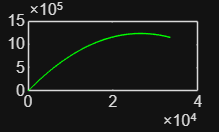

%assumes monopoly with infinite resource and no interest
Q_space = 0:500:sum(production_cap);
monopoly_price = price_per_day(P, Q_space, demand_shock, supply_shock);
monopoly_profit = Q_space .* (monopoly_price - marginal_cost(7));
plot(Q_space, monopoly_profit, 'g');

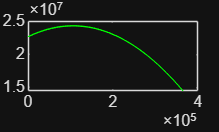


%assumes monopoly with finite resource and endgame
%assumes no interest
Q_space_finite = 0:5000:sum(reserves);
Q_reserve_finite = max(Q_space_finite);
monopoly_price_finite = price_per_day(P, Q_space_finite./net_days, demand_shock, supply_shock);
monopoly_profit_production = Q_space_finite .* (monopoly_price_finite - marginal_cost(7));
monopoly_profit_leftover = (Q_reserve_finite - Q_space_finite) * (endgame_bbl - marginal_cost(7));
monopoly_profit_finite = monopoly_profit_production + monopoly_profit_leftover;
plot(Q_space_finite, monopoly_profit_finite, 'g');

monopoly_profit_finite_max = max(monopoly_profit_finite);